# Lattice Modulation, Scan Force

## Set atom and magnetic field

% atom
atom = Alkali("Lithium7");

% B field
bList = num2cell(linspace(1.2e-2,1.35e-2,1));
bList = {-1.2e-2};
niB = 543.6e-4; %non-interacting feshbach field
bField = cellfun(@(x) MagneticField(...
    bias = [0;0;niB],...
    gradient = [0,0,0;0,0,0;0,x,0]),bList,'UniformOutput',false);

## Set benchmark simulation

% set laser
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 0.6, ...
    waist = 110e-6 ...
    );
laser = {laser};

% set optical lattice
ol = OpticalLattice(atom,laser{1});
ol.DepthSpec = 8.8458 * ol.RecoilEnergy;
ol.updateIntensity;
kL = ol.Laser.AngularWavenumber;
laser = {ol.Laser};


% set modulation
sWave = SineWave( ...
    amplitude=0.035 * 2, ...
    duration=15e-3, ...
    frequency=143.2231e3, ...
    startTime=0);
latticeMod = WaveformList("LatticeMod");
latticeMod.WaveformOrigin = {sWave};
latticeMod = {latticeMod};

% Initial condition
ic = InitialCondition("LatticeFourierSeSim1D");

ans =   DynamicProperty with properties:

                    Name: 'QuasiMomentum'
             Description: ''
     DetailedDescription: ''
               GetAccess: 'public'
               SetAccess: 'public'
               Dependent: 0
                Constant: 0
                Abstract: 0
               Transient: 0
                  Hidden: 0
           GetObservable: 0
           SetObservable: 0
                AbortSet: 0
             NonCopyable: 1
    PartialMatchPriority: 1
               GetMethod: []
               SetMethod: []
              HasDefault: 0
              Validation: [0×0 meta.Validation]
           DefiningClass: [0×0 meta.class]


ic.QuasiMomentum = 0.7 * kL;
[~,ic.WaveFunction] = ol.computeBand1D(ic.QuasiMomentum,1);


se = LatticeFourierSeSim1D("Test", ...
    laser = laser,...
    magneticField = bField,...
    latticeModulation = latticeMod,...
    timeStep=1e-7,...
    totalTime=3.33e-3,...
    initialCondition = ic);

Constructing the object.
Setting up folders.
Creating a database entry.
Updating the object file.



se.start

Updating the object file.
Updating the object file.
Updating the object file.
All runs are completed.
Updating the object file.


## Plot

% plot benchmark
trialNumber = 7;
obj = loadTrial(createReader("simulation"),"lattice_fourier_simulation_1d",trialNumber);

% obj.SimRun(1).showSpaceTime
% nRun = numel(obj.SimRun);
% freqList = zeros(1,nRun);
% ampList = zeros(1,nRun);
% for ii = 1:nRun
%     rawData = obj.SimRun(ii).showPeak;
%     fitData = SineFit1D(rawData);
%     fitData.do;
%     freqList(ii) = fitData.Coefficient(2);
%     ampList(ii) = fitData.Coefficient(1);
% end

## Analysis: animation

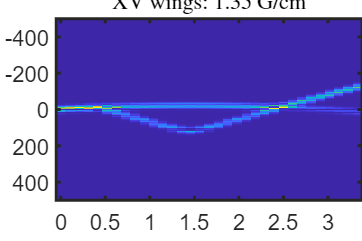

trialNumber = 21;
filename = "AI_Force_Scan.gif";
startDelay=.5;
midDelay=.1;
endDelay=.5;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
nSpace = obj.SimRun(1).NSpaceStep;
nRun = numel(obj.SimRun);
psiList = zeros(nRun,nSpace);
psi1 = obj.SimRun(1).readRun("WaveFunction");
psi1 = psi1(1,:);
n1 = abs(psi1).^2;
nLim = max(n1);
for ii = 1:nRun
    psiList(ii,:) = obj.SimRun(ii).readRun("FinalWaveFunction");
    obj.SimRun(ii).showSpaceTime;
    fig = gcf;
    imgAxes = gca;
    imgAxes.CLim = [0,nLim];

    % Update title
    imgAxes.Title.String = "XV wings: $" + num2str(norm(bField{ii}.GradientLu)) + "~\mathrm{G/cm}$";
    imgAxes.Title.Interpreter = "latex";
    render

    % Save as gif
    frame = getframe(fig);
    im = frame2im(frame);
    [A,map] = rgb2ind(im,256);
    if ii == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',startDelay);
    else
        if ii==nRun
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',endDelay);
        else
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',midDelay);
        end
    end
end

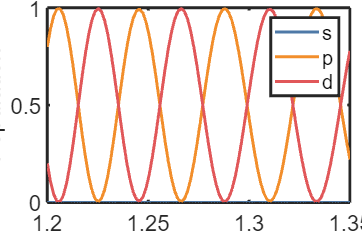

x = obj.SimRun(1).SpaceList;
bandPop = ol.computeBandPopulation1D(psiList,int32(2),x);
bListGauss = cell2mat(bList) * 1e2;
figure
plot(bListGauss,bandPop)
xlabel("XV wings field gradient [Gauss/cm]")
ylabel("Population")
legend("s","p","d")
render
saveas(gcf,"AI_Force_Scan","png")

trialNumber = 16;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
